%% Machine Learning
% Exercise 1: Linear Regression
% --- Housing Prices ---
%{
In this part, you will implement linear regression with multiple variables to
predict the prices of houses. Suppose you are selling your house and you
want to know what a good market price would be. One way to do this is to
�rst collect information on recent houses sold and make a model of housing
prices.
%}

%% %% Initialization
clear ; close all; clc % Clear and close figures

%% Load Data
data = load('ex1data2.txt')

data =         2104           3      399900
        1600           3      329900
        2400           3      369000
        1416           2      232000
        3000           4      539900
        1985           4      299900
        1534           3      314900
        1427           3      198999
        1380           3      212000
        1494           3      242500


%% Parsing data
X_origin = data(:, 1:2);
X = data(:, 1:2); % x1:size (0-2000 feet^2) and x2: number of bedrooms (1-5)
Y = data(:, 3); % dollar
m = length(Y);

% Print out some data points
fprintf('First 10 examples from the dataset: \n');

First 10 examples from the dataset: 


fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) Y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


%% Scale Features and set them to zero mean
% Feature scaling and mean normalization:
% Scale features and set them to zero mean

[X avg sigma] = featureNormalize(X);

% Add intercept term to X
X = [ones(m, 1) X]

X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


%% Gradient Descent

% Choose some learning_rate value
lr = 0.01; % learning_rate
epochs = 400;

% Init Weights and run Gradient Descent
w = zeros(3,1);
[w, C_history] = gradientDescentMulti(X, Y, w, lr, epochs);

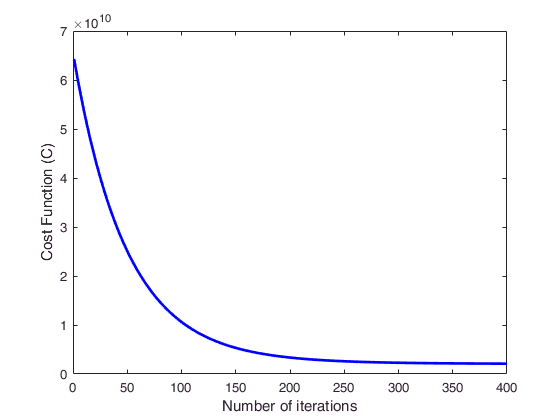

%% Plot the convergence graph
figure;
plot(1:numel(C_history), C_history, '-b', 'LineWidth', 2);
% n = numel(A) returns the number of elements, n, in array A, equivalent to prod(size(A)).
xlabel('Number of iterations');
ylabel('Cost Function (C)');


% Display gradient descent's result
%Weights computed from gradient descent:
fprintf(' %f \n', w);

 334302.063993 
 100087.116006 
 3673.548451 


% Estimate the price of a 1650 sq-ft, 3 br house.
FEET = 1650;
BED = 3;
price = [1 (FEET-avg(1))/sigma(1) (BED-avg(2))/sigma(2)]*w; % You should change this

fprintf(['Predicted price of a 1650 sq-ft, 3 br house ' ...
         '(using gradient descent):\n $%f\n'], price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $289314.620338
